clear
clc
close all

#### Un sistema de referencia OXYZ se gira 45º con respecto a su eje X y posteriormente otros 45º con respecto a su eje Z’ intrínseco o relativo (ya girado). 

        a. Construye las matrices básicas de rotación con respecto a cada eje, y calcula la matriz final de rotación R que representa ambos giros. 

M_x=rotx(45)

M_x =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


M_z=rotz(45)

M_z =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000



M=M_x*M_z

M =     0.7071   -0.7071         0
    0.5000    0.5000   -0.7071
    0.5000    0.5000    0.7071


        b.Representa gráficamente la orientación del sistema final girado basándote en las columnas de la matriz de rotación.

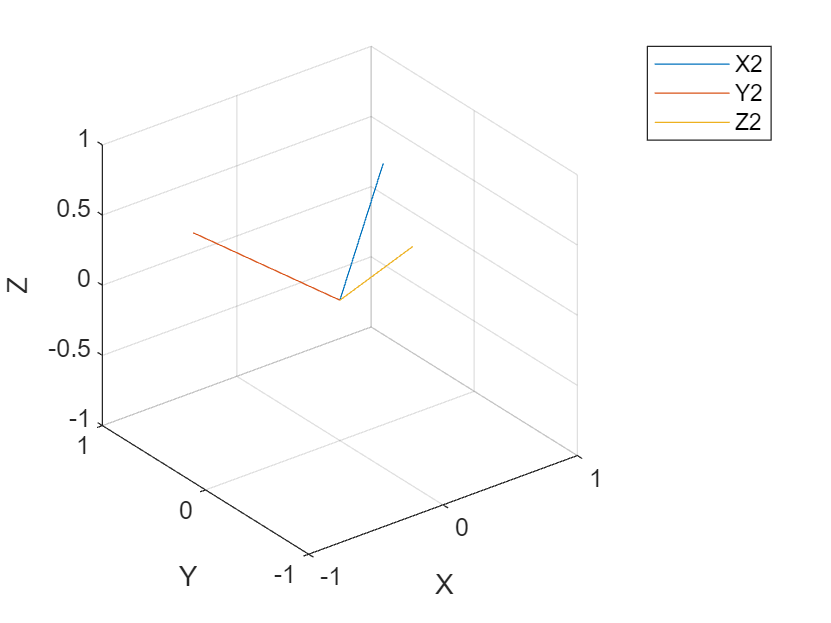

ejeX=M(:,1);
ejeY=M(:,2);
ejeZ=M(:,3);

figure();
plot3([0, ejeX(1)],[0, ejeX(2)],[0, ejeX(3)]);
hold on
plot3([0, ejeY(1)],[0, ejeY(2)],[0, ejeY(3)]);
plot3([0, ejeZ(1)],[0, ejeZ(2)],[0, ejeZ(3)]);
grid on
xlabel('X')
ylabel('Y')
zlabel('Z')
xlim([-1 1]);
ylim([-1 1]);
zlim([-1 1]);

legend('X2', 'Y2', 'Z2')

        c.Comprueba el resultado mediante la aplicación Rotation Viewer para MATLAB. 

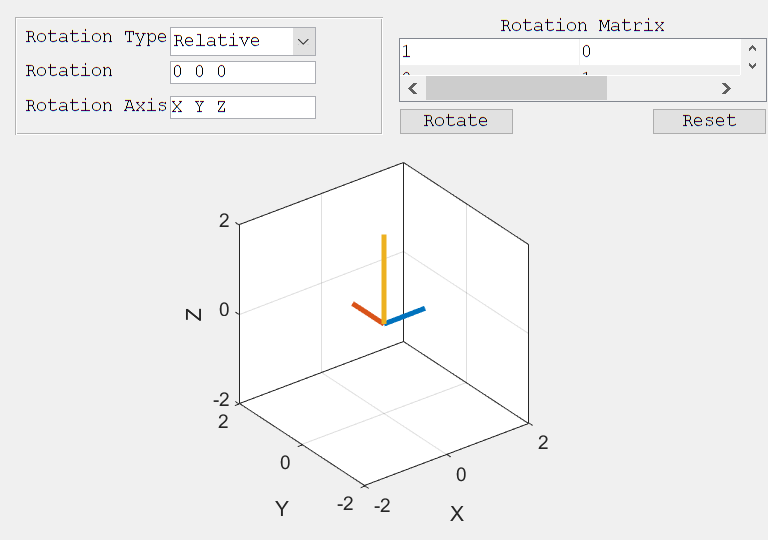

RotationViewer;

        d.Realiza las rotaciones en orden inverso e indica si el resultado es el mismo. 

M2=M_z*M_x

M2 =     0.7071   -0.5000    0.5000
    0.7071    0.5000   -0.5000
         0    0.7071    0.7071


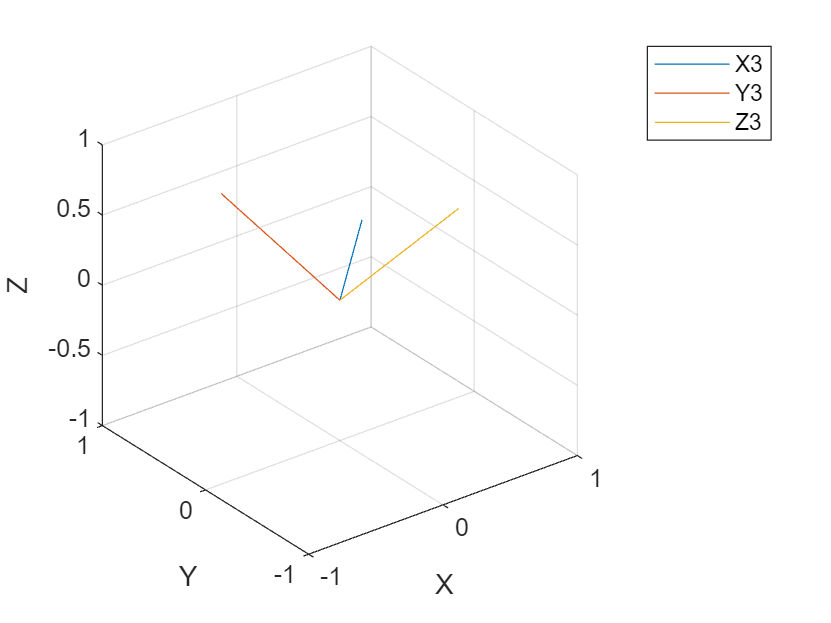


ejeX=M2(:,1);
ejeY=M2(:,2);
ejeZ=M2(:,3);

figure();
plot3([0, ejeX(1)],[0, ejeX(2)],[0, ejeX(3)]);
hold on
plot3([0, ejeY(1)],[0, ejeY(2)],[0, ejeY(3)]);
plot3([0, ejeZ(1)],[0, ejeZ(2)],[0, ejeZ(3)]);
grid on
xlabel('X')
ylabel('Y')
zlabel('Z')
xlim([-1 1]);
ylim([-1 1]);
zlim([-1 1]);

legend('X3', 'Y3', 'Z3')